already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the delta!
already enter in the

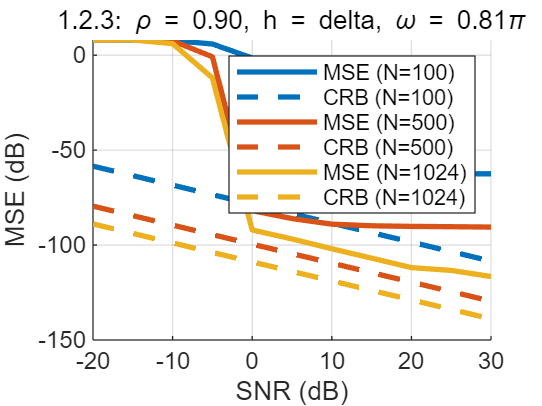

enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the filter
enter in  the

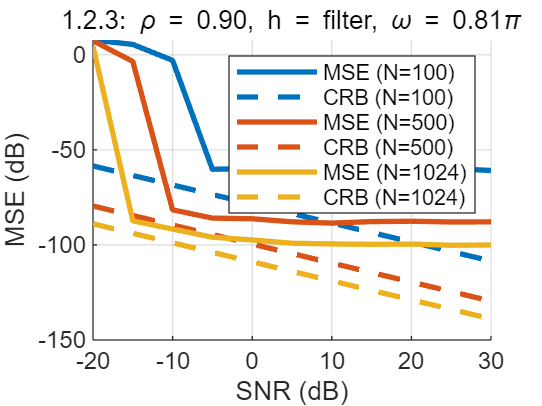

clear; clc;

% Fun_2_1();
% Fun_2_2();
Fun_2_3();



% % ==== 参数设置 ====
% function Fun_2_1()
% % 项目 1.2.1 - rho=0, h=delta, 多N值对比
% 
% a0 = 1;
% N_values = [100 500 1024];
% omega = pi/4;
% SNR_dB = -20:5:40;
% rho = 0;
% h_case = "delta";
% filter_coeffs.b = [2];
% filter_coeffs.a = [1, 0.9];
% num_simulations = 400;
% oversampling = 64;
% 
% results = simulate_estimation(N_values, SNR_dB, omega, rho, h_case, filter_coeffs, a0, oversampling, num_simulations);
% 
% % 绘图
% figure; hold on;
% color_map = lines(length(N_values));
% for i = 1:length(N_values)
%     plot(SNR_dB, 10*log10(results.MSE(i,:)), '-', 'Color', color_map(i,:), ...
%         'DisplayName', sprintf('MSE (N=%d)', N_values(i)), 'LineWidth', 2);
%     plot(SNR_dB, 10*log10(results.CRB(i,:)), '--', 'Color', color_map(i,:), ...
%         'DisplayName', sprintf('CRB (N=%d)', N_values(i)), 'LineWidth', 2);
% end
% xlabel('SNR (dB)'); ylabel('MSE (dB)');
% title('1.2.1: h=\delta, \rho=0');
% legend show; grid on;
% end
% 
% function Fun_2_2()
% % 项目 1.2.2 - rho=0, h=filter, 多N值对比
% 
% a0 = 1;
% N_values = [100 500 1024];
% omega = pi/4;
% SNR_dB = -20:5:40;
% rho = 0;
% h_case = "filter";
% filter_coeffs.b = [2];
% filter_coeffs.a = [1, 0.9];
% num_simulations = 400;
% oversampling = 64;
% 
% results = simulate_estimation(N_values, SNR_dB, omega, rho, h_case, filter_coeffs, a0, oversampling, num_simulations);
% 
% % 绘图
% figure; hold on;
% color_map = lines(length(N_values));
% for i = 1:length(N_values)
%     plot(SNR_dB, 10*log10(results.MSE(i,:)), '-', 'Color', color_map(i,:), ...
%         'DisplayName', sprintf('MSE (N=%d)', N_values(i)), 'LineWidth', 2);
%     plot(SNR_dB, 10*log10(results.CRB(i,:)), '--', 'Color', color_map(i,:), ...
%         'DisplayName', sprintf('CRB (N=%d)', N_values(i)), 'LineWidth', 2);
% end
% xlabel('SNR (dB)'); ylabel('MSE (dB)');
% title('1.2.2: h=filter, \rho=0');
% legend show; grid on;
% end

function Fun_2_3()
% 项目 1.2.3：比较 h = delta 和 h = filter
% 每个 h_case 输出一张图，图中三条曲线代表不同 N 值

a0 = 1;
N_values = [100 500 1024];
% omega = pi/4;
omega = 0.81*pi;
SNR_dB = -20:5:30;
rho = 0.9;
filter_coeffs.b = [2];
filter_coeffs.a = [1, 0.9];
num_simulations = 100;
oversampling = 64;

h_cases = ["delta", "filter"];  % 两种滤波结构
colors = lines(length(N_values));  % 每个N值一种颜色

for k = 1:length(h_cases)
    h_case = h_cases(k);
    results = simulate_estimation(N_values, SNR_dB, omega, rho, h_case, filter_coeffs, a0, oversampling, num_simulations);
    
    figure; hold on;
    for i = 1:length(N_values)
        plot(SNR_dB, 10*log10(results.MSE(i,:)), '-', ...
            'Color', colors(i,:), 'LineWidth', 2, ...
            'DisplayName', sprintf('MSE (N=%d)', N_values(i)));
        
        plot(SNR_dB, 10*log10(results.CRB(i,:)), '--', ...
            'Color', colors(i,:), 'LineWidth', 2, ...
            'DisplayName', sprintf('CRB (N=%d)', N_values(i)));
    end
    
    xlabel('SNR (dB)');
    ylabel('MSE (dB)');
    title(sprintf('1.2.3: \\rho = %.2f, h = %s, \\omega = %.2f\\pi', rho, h_case, omega/pi));
    legend show; grid on;
end
end



function results = simulate_estimation(N_values, SNR_dB, omega_true, rho, h_case, filter_coeffs, a0, oversampling, num_simulations)
results = struct();
results.MSE = zeros(length(N_values), length(SNR_dB));
results.CRB = zeros(length(N_values), length(SNR_dB));

for i = 1:length(N_values)
    N = N_values(i);
    for j = 1:length(SNR_dB)
        snr_linear = 10^(SNR_dB(j)/10);
        sigma_w2 = a0 / (2 * snr_linear);
        omega_estimates = zeros(num_simulations, 1);
        for run = 1:num_simulations
            [s, w] = generate_signal(N, omega_true, sigma_w2, rho);
            x = s + w;
            if h_case == "filter"
                x = filter_signal(s, filter_coeffs) + w;                
                disp('enter in  the filter');
            elseif h_case == "delta"
                disp('already enter in the delta!');
            end
            omega_estimates(run) = estimate_frequency_fft(x, N, oversampling);
        end
        results.MSE(i, j) = mean((omega_estimates - omega_true).^2);
        % results.CRB(i, j) = compute_crb(N, snr_linear);
        % results.CRB(i, j) = compute_crb_general(N, snr_linear, omega_true, rho);
        results.CRB(i, j) = compute_crb_filtered_colored(N, omega_true, snr_linear, rho, filter_coeffs.b, filter_coeffs.a);
    end
end
end


function omega_estimate = estimate_frequency_fft(x, N, oversampling)
N_fft = oversampling * N;
X = fft(x, N_fft);
P = abs(X(1:N_fft/2)).^2;
[~, idx_max] = max(P);

if idx_max <= 1 || idx_max >= length(P) - 1
    omega_estimate = 2 * pi * (idx_max - 1) / N_fft;
else
    alpha = P(idx_max - 1);
    beta = P(idx_max);
    gamma = P(idx_max + 1);
    delta = 0.5 * (alpha - gamma) / (alpha - 2*beta + gamma);
    f_refined = (idx_max - 1 + delta) / N_fft;
    omega_estimate = 2 * pi * f_refined;
end
end


function [s, w] = generate_signal(N, omega, sigma_w2, rho)
A = 1;
phi_0 = 2 * pi * rand();
n = (0:N-1)';
s = A * cos(omega * n + phi_0);
Cww = sigma_w2 * rho.^(abs((1:N)' - (1:N)));
A_cov = sqrtm(Cww);
w = A_cov * randn(N, 1);
end

function x_filtered = filter_signal(x, filter_coeffs)
x_filtered = filter(filter_coeffs.b, filter_coeffs.a, x);
end

% function crb = compute_crb(N, snr_linear)
% crb = 6 / (snr_linear * N * (N - 1) * (2 * N - 1));
% end

% function crb = compute_crb_general(N, snr_linear, omega, rho)
%     A = 1;
%     phi_0 = 0; % 可任意设为 0，因其不影响偏导项
%     n = (0:N-1)';
%     s = A * cos(omega * n + phi_0);
% 
%     % 计算一阶导数
%     dmu_domega = -A * n .* sin(omega * n + phi_0);
% 
%     % 构造协方差矩阵
%     sigma_w2 = A^2 / (2 * snr_linear);
%     Cww = sigma_w2 * rho .^ abs((1:N)' - (1:N));
% 
%     % Fisher 信息矩阵
%     Fisher = dmu_domega' * (Cww \ dmu_domega);
%     crb = 1 / Fisher;
% end
function crb = compute_crb_filtered_colored(N, omega, snr_linear, rho, b, a)
    A = 1;
    phi = 0;
    n = (0:N-1)';

    % 信号与导数
    s = A * cos(omega * n + phi);
    ds_domega = -A * n .* sin(omega * n + phi);

    % 滤波器作用于信号（滤波器不作用于噪声）
    s_filtered = filter(b, a, s);
    ds_filtered = filter(b, a, ds_domega);

    % 构造 colored noise 协方差矩阵
    sigma_w2 = A^2 / (2 * snr_linear);
    Cww = sigma_w2 * rho .^ abs((1:N)' - (1:N));   % Toeplitz

    % CRB 计算
    Fisher = ds_filtered' * (Cww \ ds_filtered);
    crb = 1 / Fisher;
end



